# System Dynamics Analysis Using Laplace Transform

clear; clc;

% ODE: \ddot(x) + d*\dot(x) + k*x = u(t);

d = 5;
k = 4;
s = tf('s');
sys = 1/(s^2+d*s+k);

## Response with perturbation

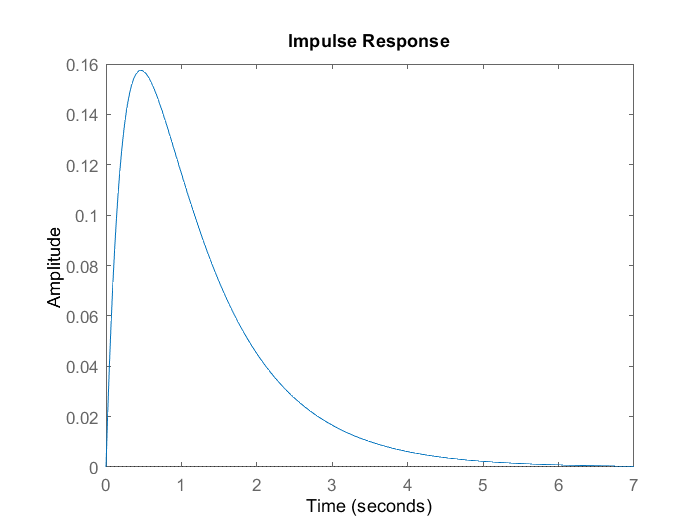

figure(1);
impulse(sys);

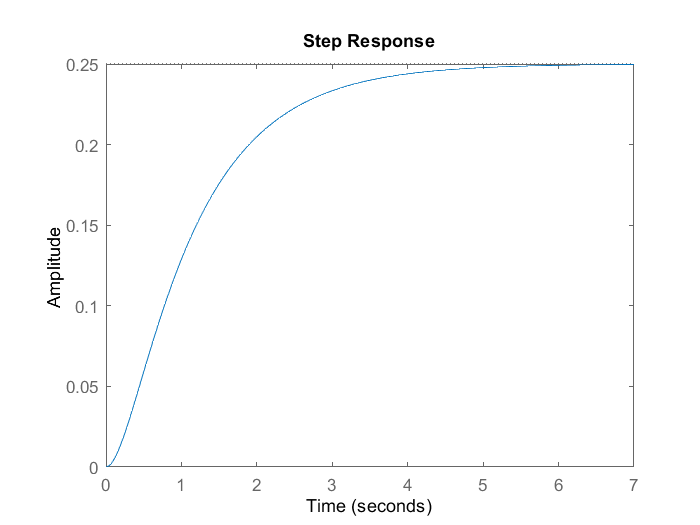

figure(2);
step(sys);

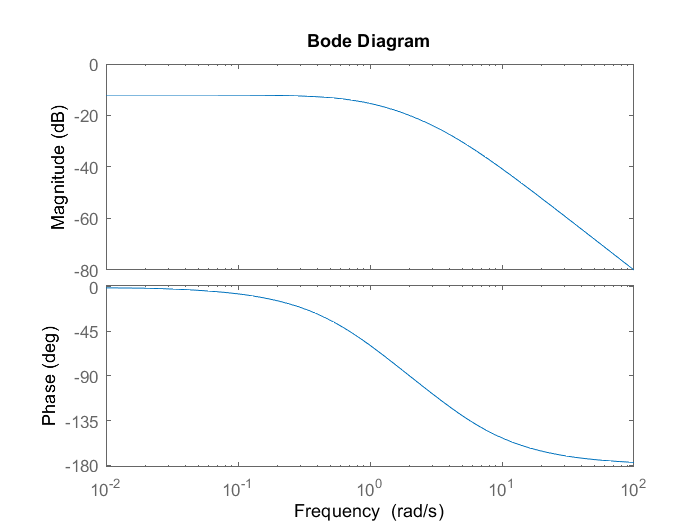

figure(3)
bode(sys);

## Step response

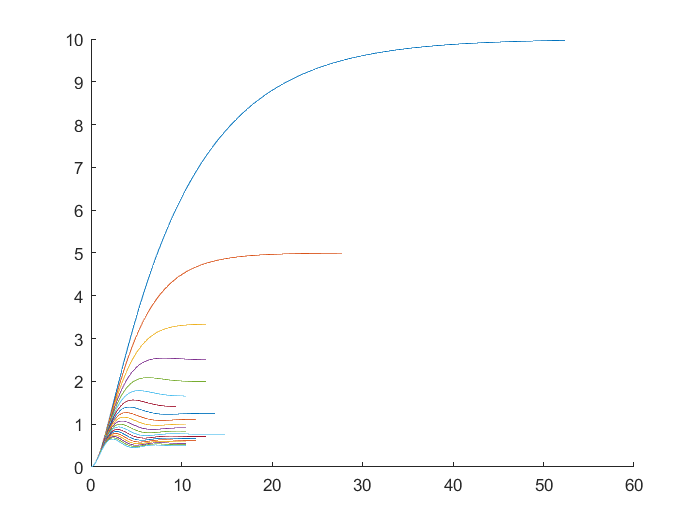

% Constant damping with changing spring
d = 1;
figure(4);
axes;
hold on;
for k = 0.1:0.1:2
    sys = 1/(s^2+d*s+k);
    [y,t] = step(sys);
    plot(t,y);
end

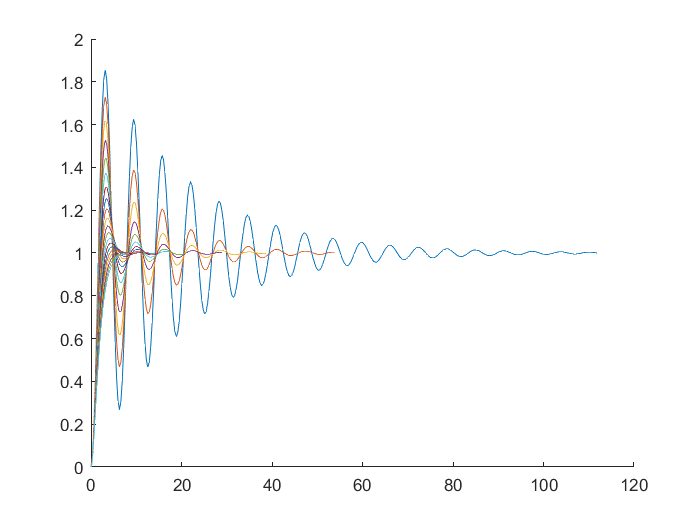

% Constant spring with changing damping
k = 1;
figure(5);
axes;
hold on;
for d = 0.1:0.1:2
    sys = 1/(s^2+d*s+k);
    [y,t] = step(sys);
    plot(t,y);
end

## Bode plot

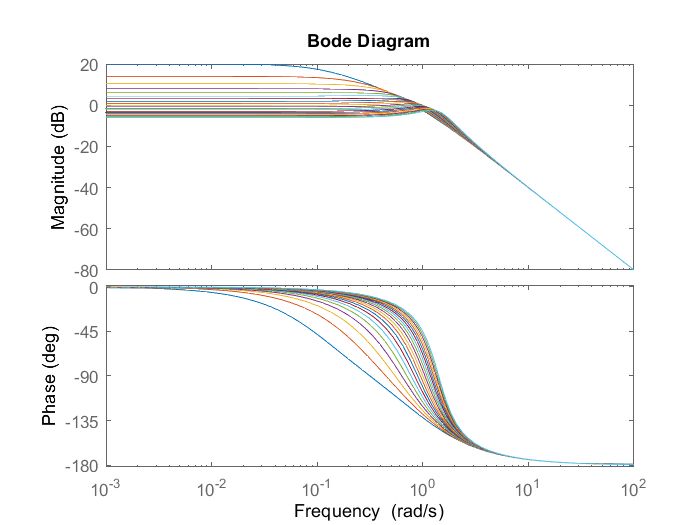

% Constant damping with changing spring
d = 1;
figure(6);
axes;
hold on;
for k = 0.1:0.1:2
    sys = 1/(s^2+d*s+k);
    bode(sys);
end

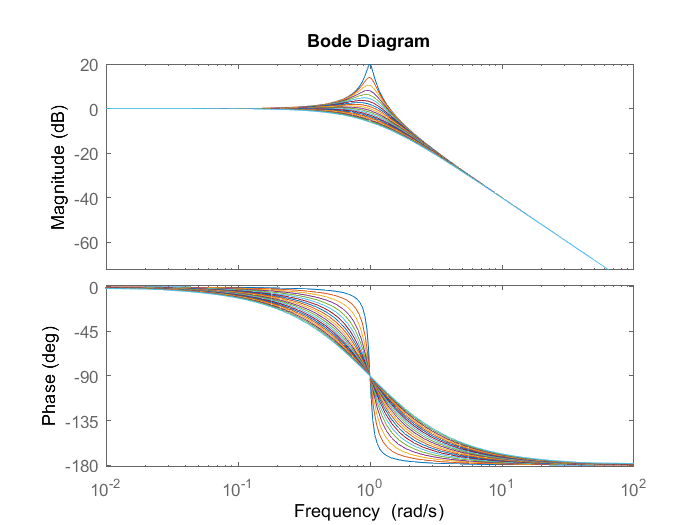

% Constant spring with changing damping
k = 1;
figure(7);
axes;
hold on;
for d = 0.1:0.1:2
    sys = 1/(s^2+d*s+k);
    bode(sys);
end